%some constants
sigma = 10;
r = 28;
b = 8/3;

## Butterfly effect (single oscilator)

N = 1; %number of nodes
x0 = randn(3*N,1)*0.1; %starting position
f = @(t,x,N,sigma,r,b,C)[
    sigma*(x(N+1:2*N)-x(1:N)); %dx
    r*x(1:N) - x(N+1:2*N) - x(1:N).*x(2*N+1:3*N); %dy
    -b*x(2*N+1:3*N) + x(1:N).*x(N+1:2*N); %dz
] %system of equations

f = function_handle with value:
    @(t,x,N,sigma,r,b,C)[sigma*(x(N+1:2*N)-x(1:N));r*x(1:N)-x(N+1:2*N)-x(1:N).*x(2*N+1:3*N);-b*x(2*N+1:3*N)+x(1:N).*x(N+1:2*N)]


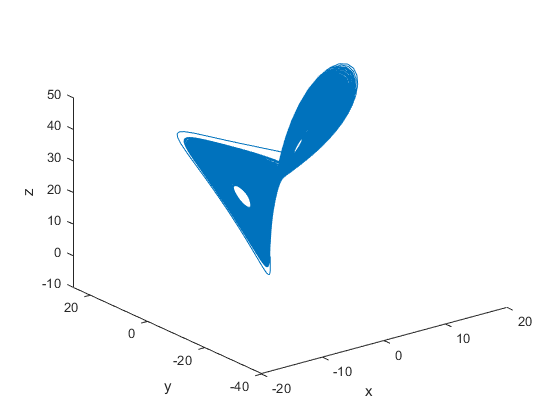

tspan = [0 2000]; %timespan
x0 = randn(3*N,1)*1e-1; %random starting positions
[T, X] = ode45(@(t,x)f(t,x,N,sigma,r,b,C),tspan,x0); %running the simulation

figure()
clf
plot3(X(:,1),X(:,2),X(:,3))
xlabel('x')
ylabel('y')
zlabel('z')

## Multiple oscilators

N = 4; %number of nodes
x0 = randn(3*N,1)*10;
f = @(t,x,N,sigma,r,b,C)[
    sigma*(x(N+1:2*N)-x(1:N)); %dx
    r*x(1:N) - x(N+1:2*N) - x(1:N).*x(2*N+1:3*N); %dy
    -b*x(2*N+1:3*N) + x(1:N).*x(N+1:2*N); %dz
]

f = function_handle with value:
    @(t,x,N,sigma,r,b,C)[sigma*(x(N+1:2*N)-x(1:N));r*x(1:N)-x(N+1:2*N)-x(1:N).*x(2*N+1:3*N);-b*x(2*N+1:3*N)+x(1:N).*x(N+1:2*N)]


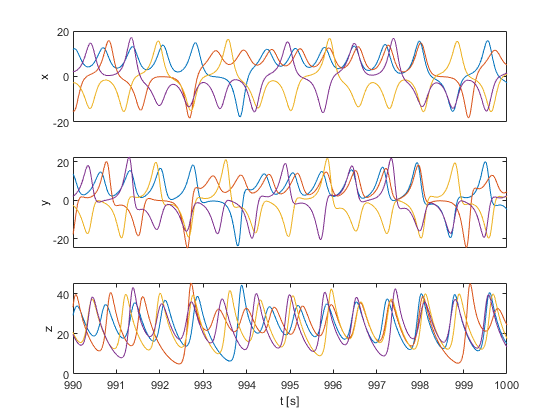

tspan = [0 1000]; %time span over which to simulate
x0 = randn(3*N,1)*10; %setting random starting positions
[T, X] = ode45(@(t,x)f(t,x,N,sigma,r,b,C),tspan,x0);

plot3Ddata(N,T,X,false,10) %as can be seen no synchronization occurs

N = 6; %number of nodes
m =[1 2;
    2 3;
    3 4;
    3 5;
    4 6;
    5 6;]; %connections
c_star = 1;
C = create_laplacian(N,m)*c_star; %creating the laplacian matrix

f = @(t,x,N,sigma,r,b,C)[
    sigma*(x(N+1:2*N)-x(1:N)) - C*x(1:N); %dx
    r*x(1:N) - x(N+1:2*N) - x(1:N).*x(2*N+1:3*N); %dy
    -b*x(2*N+1:3*N) + x(1:N).*x(N+1:2*N); %dz
]

f = function_handle with value:
    @(t,x,N,sigma,r,b,C)[sigma*(x(N+1:2*N)-x(1:N))-C*x(1:N);r*x(1:N)-x(N+1:2*N)-x(1:N).*x(2*N+1:3*N);-b*x(2*N+1:3*N)+x(1:N).*x(N+1:2*N)]


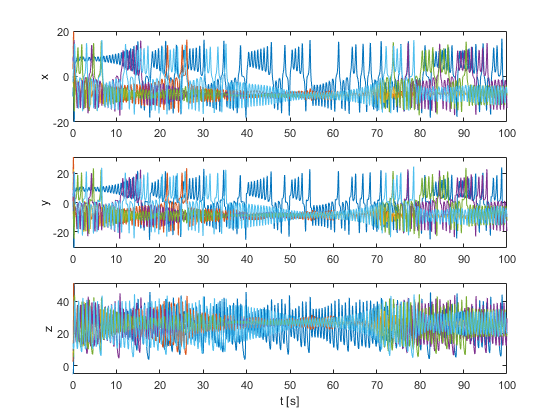

tspan = [0 100];
x0 = randn(3*N,1)*10;
[T, X] = ode45(@(t,x)f(t,x,N,sigma,r,b,C),tspan,x0);

plot3Ddata(N,T,X,false)

x = num2str([1:N]')

x = 6×1 char array
    '1'
    '2'
    '3'
    '4'
    '5'
    '6'


['x' x(1)]

ans = 'x1'

arrayfun(@(n)(n+1),x)

ans =     50
    51
    52
    53
    54
    55


(append('x',x(1)))'

ans = 2×1 char array
    'x'
    '1'


arrayfun(@(n)(['x' n]),num2str([1:N]'),'UniformOutput',false)

ans = 6×1 cell array
    {'x1'}
    {'x2'}
    {'x3'}
    {'x4'}
    {'x5'}
    {'x6'}




N = 6; %number of nodes
m =[1 2;
    2 3;
    3 4;
    3 5;
    4 6;
    5 6;]; %connections
c_star = 100;
C = create_laplacian(N,m)*c_star; %creating the laplacian matrix

%creating the connectivity matrix D
%m = [5 6];
m = []


m =

     []



D = create_laplacian(N,m)*20

D =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0



f = @(t,x,N,sigma,r,b,C)[
    sigma*(x(N+1:2*N)-x(1:N)) - C*x(1:N); %dx
    r*x(1:N) - x(N+1:2*N) - x(1:N).*x(2*N+1:3*N) - D*x(N+1:2*N); %dy
    -b*x(2*N+1:3*N) + x(1:N).*x(N+1:2*N); %dz
]

f = function_handle with value:
    @(t,x,N,sigma,r,b,C)[sigma*(x(N+1:2*N)-x(1:N))-C*x(1:N);r*x(1:N)-x(N+1:2*N)-x(1:N).*x(2*N+1:3*N)-D*x(N+1:2*N);-b*x(2*N+1:3*N)+x(1:N).*x(N+1:2*N)]


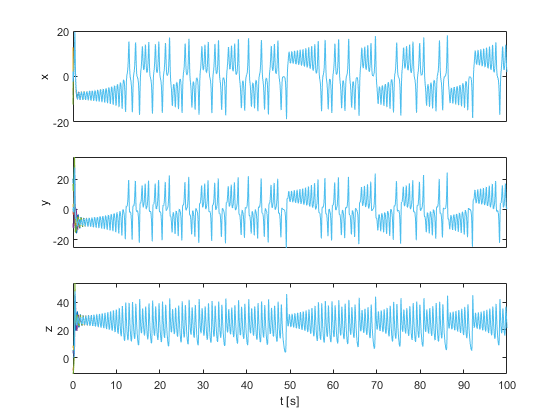

tspan = [0 100];
x0 = randn(3*N,1)*10;
[T, X] = ode45(@(t,x)f(t,x,N,sigma,r,b,C),tspan,x0);

plot3Ddata(N,T,X)